# View Decision Tree

This example shows how to view a classification or regression tree. There are two ways to view a tree: `view(tree)` returns a text description and `view(tree,'mode','graph')` returns a graphic description of the tree.

#### Create and view a classification tree.

load fisheriris 

train_index = randperm(150,50);
sample_number = 1:size(meas);
sample_number(train_index) = [];
test_index = sample_number;

train_set = meas(train_index,:);
test_set = meas(test_index,:);

tr_label = string(species(train_index));
te_label = string(species(test_index));

ctree = fitctree(train_set,tr_label); % create classification tree
view(ctree) % text description

Decision tree for classification
1  if x3<2.5 then node 2 elseif x3>=2.5 then node 3 else setosa
2  class = setosa
3  if x4<1.65 then node 4 elseif x4>=1.65 then node 5 else virginica
4  if x3<5.35 then node 6 elseif x3>=5.35 then node 7 else versicolor
5  class = virginica
6  class = versicolor
7  class = virginica



[pre_label, scores] = predict(ctree,test_set);

#### View decision tree graph

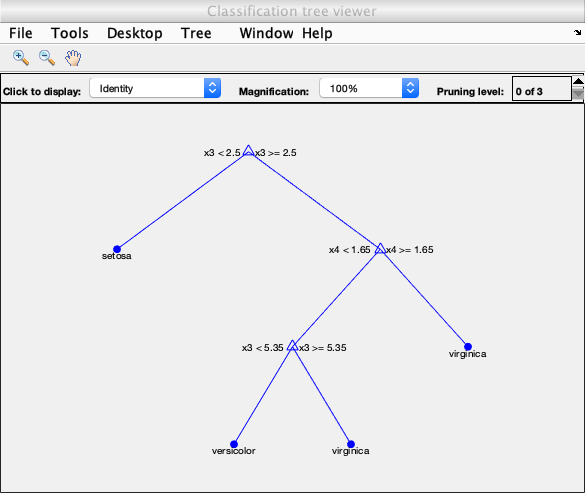

view(ctree,'mode','graph') % graphic description

#### Evaluate the classification performance

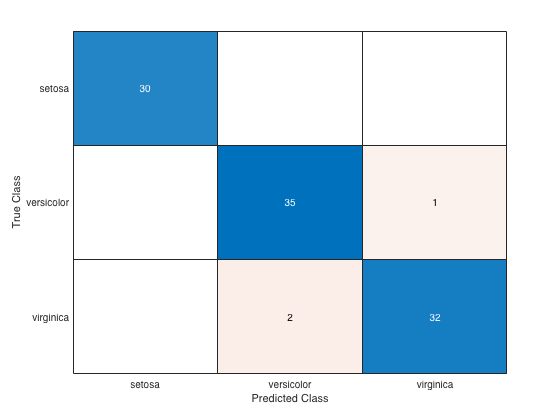

accuracy = sum(strcmp(te_label,string(pre_label)))/numel(te_label);
confusionchart(te_label,string(pre_label))